# Data analysis of Engine run on Friday May 3rd 2019

- Duration of run was 

- Captured vibration data (3D) and OBD data

### read obd and accelerometer data files

obd = readmatrix('obd_friday_main.csv');
acc = readmatrix('test_friday_real.csv');

obd_t = obd(:,1);
obd_2 = obd(:,2);
obd_tpos = obd(:,3);
obd_load = obd(:,4);
obd_5 = obd(:,5);
obd_ctemp = obd(:,6);
obd_rpm = obd(:,7);
obd_ignt = obd(:,8);
obd_vin = obd(:,9);
obd_airt = obd(:,10);
obd_map = obd(:,11);
obd_12 = obd(:,12);
obd_13 = obd(:,13);
obd_14 = obd(:,14);
obd_15 = obd(:,15);
obd_16 = obd(:,16);

acc_t = acc(:,1);
acc_x = acc(:,2);
acc_y = acc(:,4);
acc_z = acc(:,6);


acc_x(isnan(acc_x))=0;
acc_y(isnan(acc_y))=0;
acc_z(isnan(acc_z))=0;

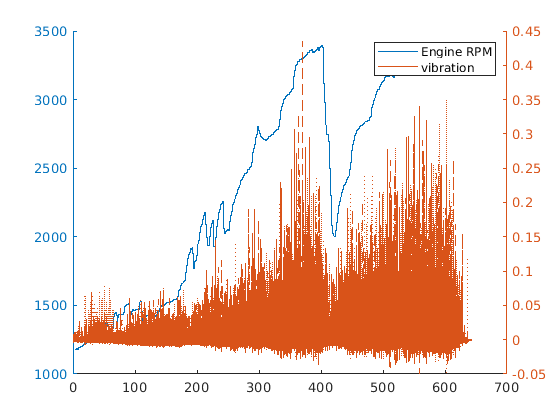

f1 = figure(1); clf;
hold on;
yyaxis left;
plot(obd_t(71:end), obd_rpm(71:end)); % time alignment
yyaxis right;
plot(acc_t, acc_x);
plot(acc_t, acc_y);
plot(acc_t, acc_z);
hold off;
legend({"Engine RPM", "vibration"});

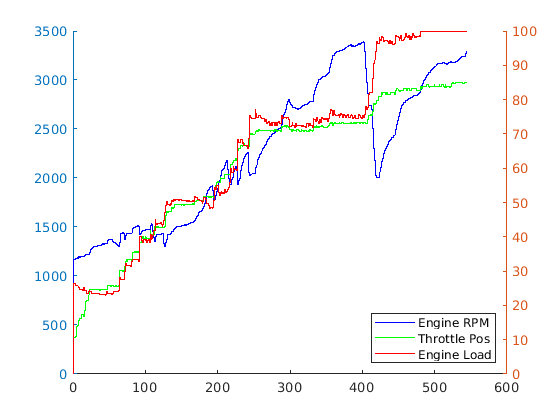

f22 = figure(22); clf;
hold on;
yyaxis left;
plot(obd_t, obd_rpm, 'b'); 
yyaxis right;
plot(obd_t, obd_tpos, 'g-');
plot(obd_t, obd_load, 'r-');
hold off;
legend({"Engine RPM", "Throttle Pos", "Engine Load"}, 'location', 'southeast');

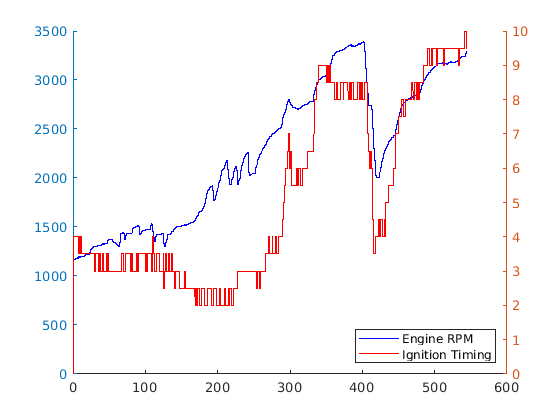

f23 = figure(23); clf;
hold on;
yyaxis left;
plot(obd_t, obd_rpm, 'b'); 
yyaxis right;
plot(obd_t, obd_ignt, 'r');
hold off;
legend({"Engine RPM", "Ignition Timing"}, 'location', 'southeast');

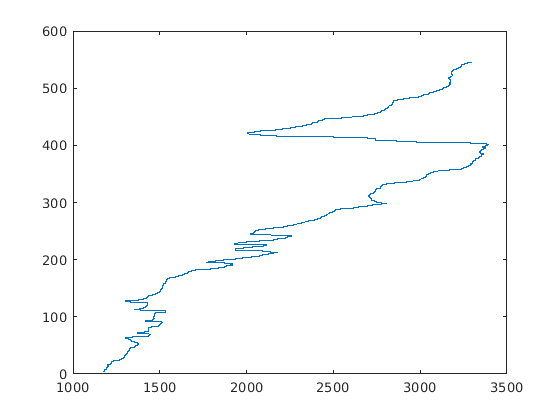

rpm_temp = obd_rpm(71:end);
obd_t_temp = obd_t(71:end);
acc_t_temp = acc_t(1:3494500);
acc_x_temp = acc_x(1:3494500);

f24 = figure(24); clf;
plot(rpm_temp, obd_t_temp);

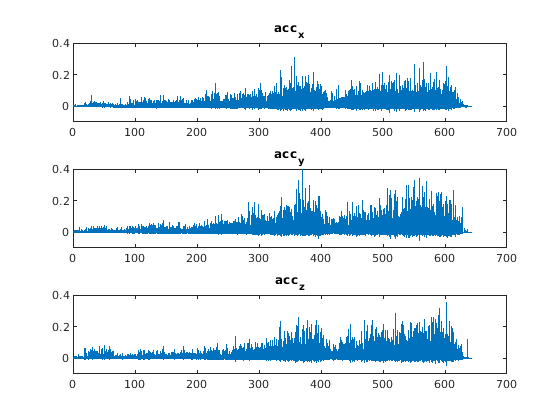

f3 = figure(3); clf;
%f3.Position = [0 0 1200 800];
title('raw accelerometer data');

subplot(311);
plot(acc_t, acc_x);
title('acc_x');
ylim([-.1 .4]);

subplot(312);
plot(acc_t, acc_y);
title('acc_y');
ylim([-.1 .4]);

subplot(313);
plot(acc_t, acc_z);
title('acc_z');
ylim([-.1 .4]);

### Spectral Analysis

sample_rate = 6400;
N = length(acc_t);

hz_vals = linspace(0, sample_rate/2, floor(N/2)+1);
powers = abs(fft(acc_x(:,1))/N).^2;


f4 = figure(4); clf;
f4.Position = [0 0 1200 800];
subplot(311);
%plot(hz_vals, powers(1:length(hz_vals)));
plot(hz_vals, fft(acc_x(1:length(hz_vals))));

title("FFT of acc_x");
ylim([-10 10]);

subplot(312);
%plot(hz_vals, powers(1:length(hz_vals)));
plot(hz_vals, fft(acc_y(1:length(hz_vals))));

title("FFT of acc_y");
ylim([-10 10]);

subplot(313);
%plot(hz_vals, powers(1:length(hz_vals)));
plot(hz_vals, fft(acc_z(1:length(hz_vals))));

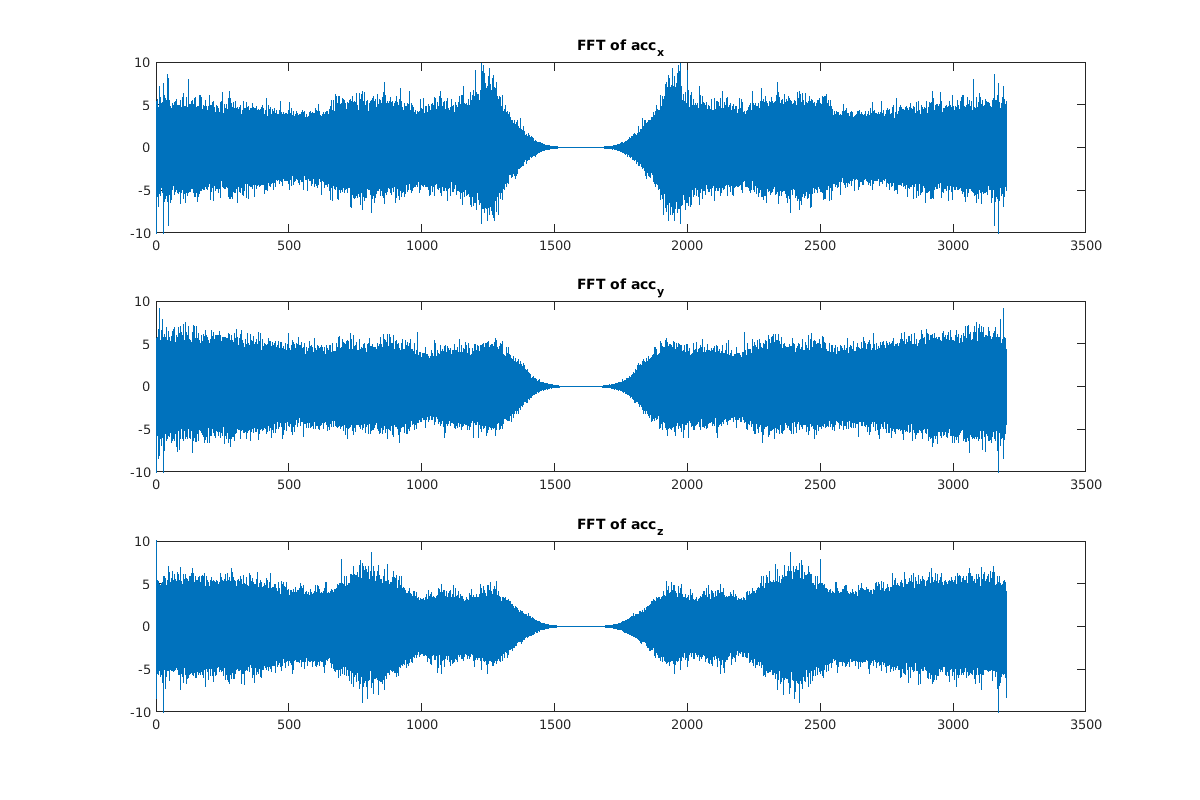

title("FFT of acc_z");
ylim([-10 10]);

### DWT of acc_x

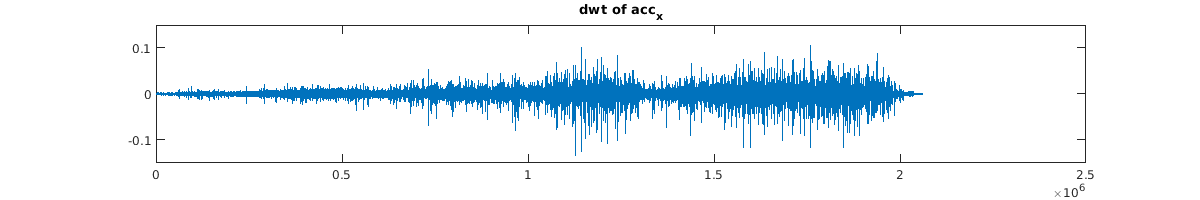

[cA, cD] = dwt(acc_x, 'sym4');
f5 = figure(5); clf;
f5.Position = [0 0 1200 200];
plot(cD);
title("dwt of acc_x");

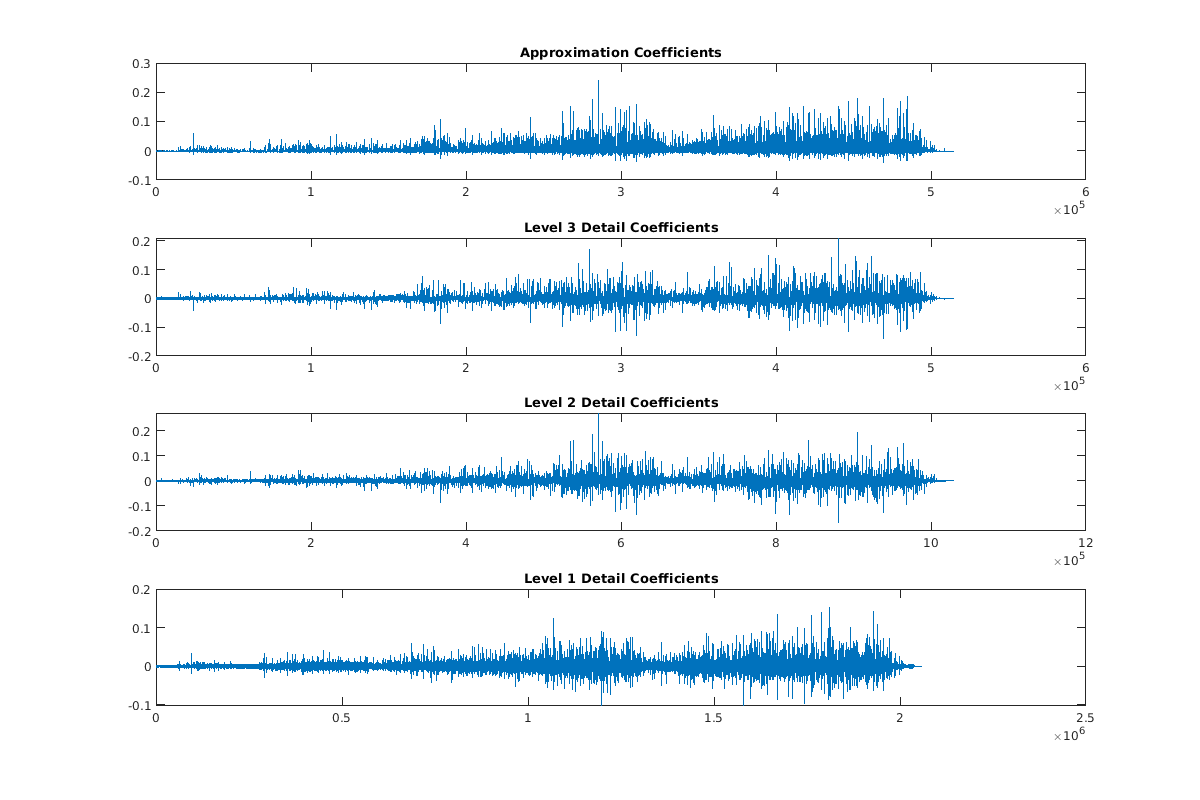

[c,l] = wavedec(acc_x, 3, 'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);
f6 = figure(6); clf;
f6.Position = [0 0 1200 800];
subplot(4,1,1);
plot(approx);
title('Approximation Coefficients');
subplot(4,1,2);
plot(cd3);
title('Level 3 Detail Coefficients');
subplot(4,1,3);
plot(cd2);
title('Level 2 Detail Coefficients');
subplot(4,1,4);
plot(cd1);
title('Level 1 Detail Coefficients');

### OBD Plots

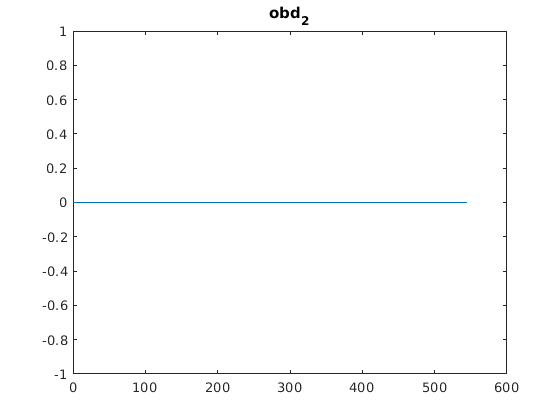

f7 = figure(7); clf;
plot(obd_t,obd_2);
title("obd_2");

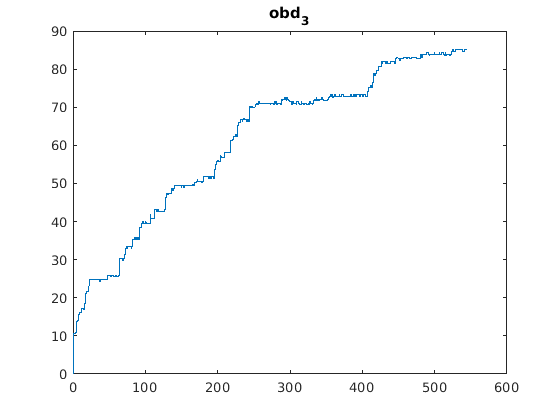

f8 = figure(8); clf;
plot(obd_t,obd_3);
title("obd_3");

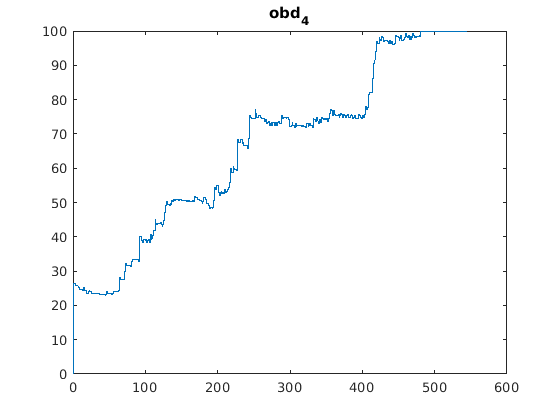

f9 = figure(9); clf;
plot(obd_t,obd_4);
title("obd_4");

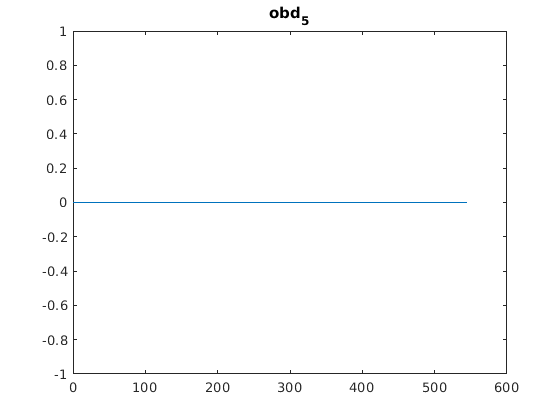

f10 = figure(10); clf;
plot(obd_t,obd_5);
title("obd_5");

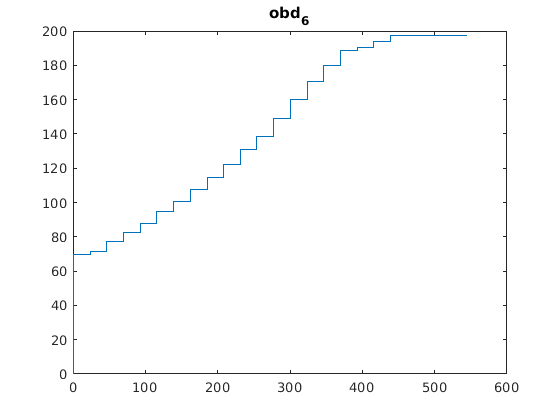

f11 = figure(11); clf;
plot(obd_t,obd_6);
title("obd_6");

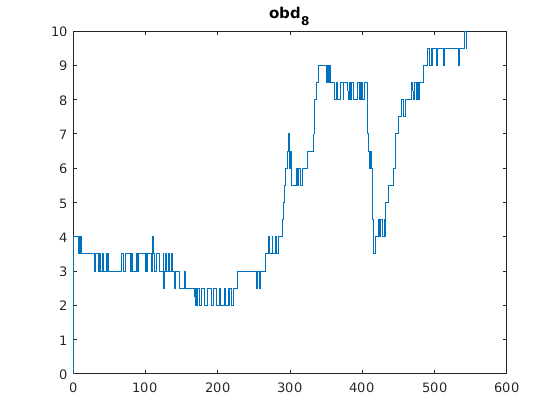

f12 = figure(12); clf;
plot(obd_t,obd_8);
title("obd_8");

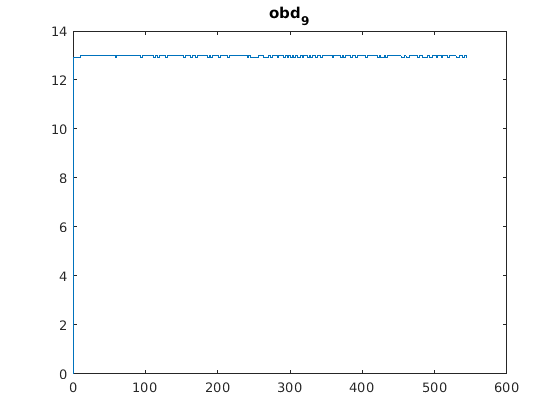

f13 = figure(13); clf;
plot(obd_t,obd_9);
title("obd_9");

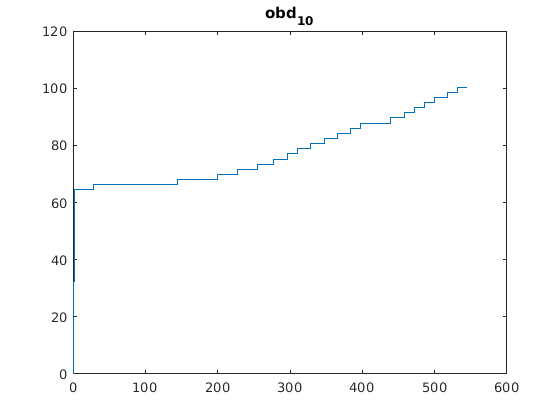

f14 = figure(14); clf;
plot(obd_t,obd_10);
title("obd_{10}");

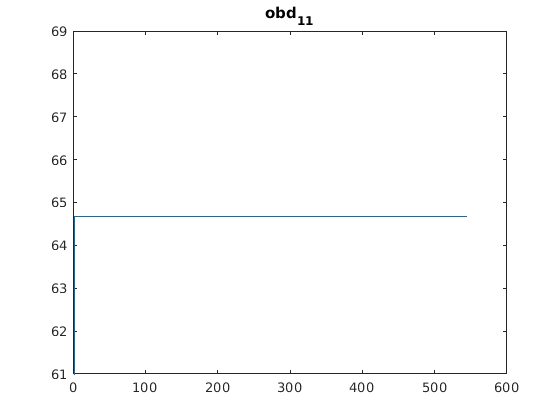

f15 = figure(15); clf;
plot(obd_t,obd_11);
ylim([61 69]);
title("obd_{11}");

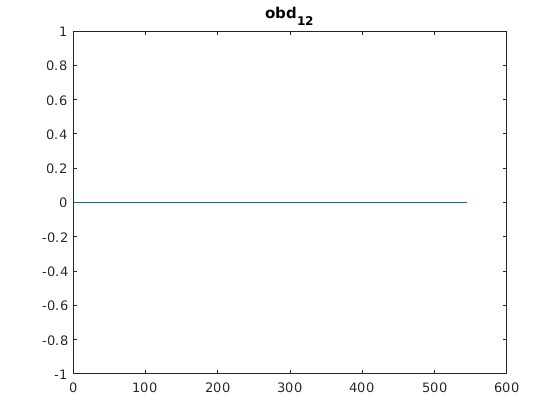

f16 = figure(16); clf;
plot(obd_t,obd_12);
title("obd_{12}");

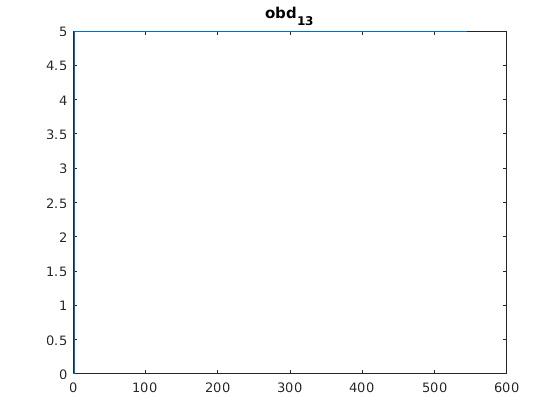

f17 = figure(17); clf;
plot(obd_t,obd_13);
title("obd_{13}");

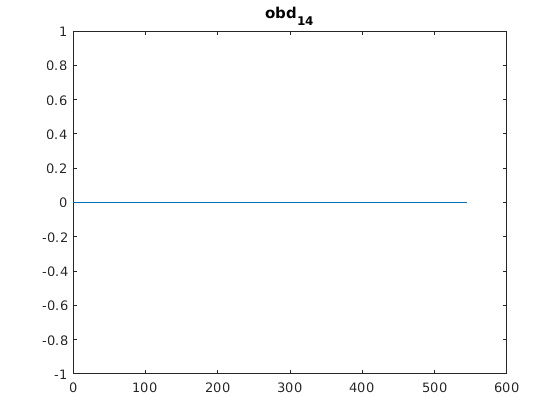

f18 = figure(18); clf;
plot(obd_t,obd_14);
title("obd_{14}");

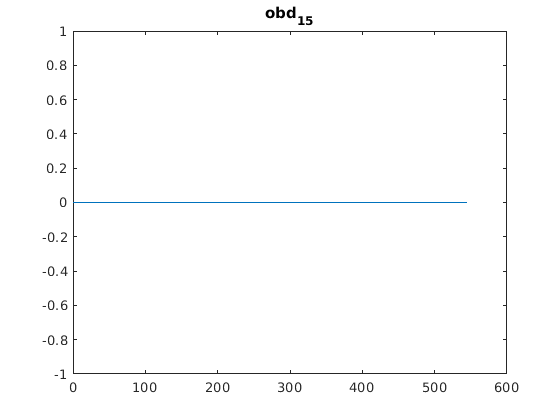

f19 = figure(19); clf;
plot(obd_t,obd_15);
title("obd_{15}");

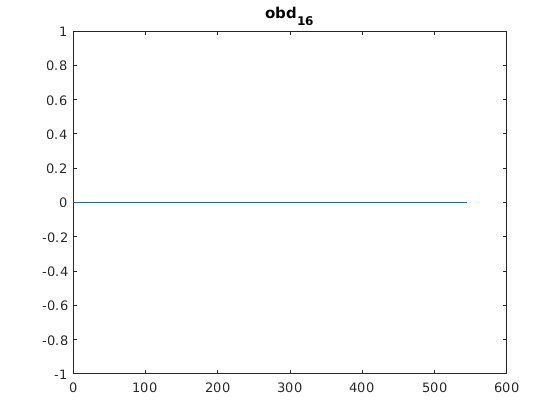

f20 = figure(20); clf;
plot(obd_t,obd_16);
title("obd_{16}");